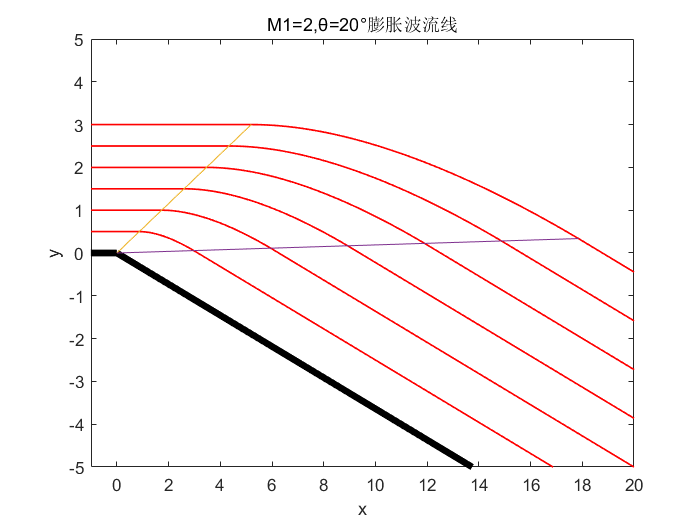

clc,clear all;
%此题关键在于构造膨胀波流线微观几何关系
%先计算出膨胀波边界
%再根据几何关系绘制膨胀波流线
%绘制波前波后流线

%求膨胀波边界
%parameters
m1 = 2;
theta = 20;

%计算v2
v1 = sqrt(6)*atand(sqrt(1/6*(m1^2-1)))-atand(sqrt(m1^2-1));%eq9.42
v2 = v1+theta; %eq9.43

%计算m2
%解非线性方程
%调用fslove函数
myfun = @(m,v) sqrt(6)*atand(sqrt(1/6*(m^2-1)))-atand(sqrt(m^2-1))-v;
fun = @(m2) myfun(m2,v2);
options = optimset('display','off');
m2 = fsolve(fun,2,options); %预估值为2

%计算边界us，uf
us = asind(1/m1); 
uf = asind(1/m2);

%绘制边界
%取边界突变点为原点
plot([-10,0],[0,0],'LineWidth',4,'Color',[0,0,0]);
hold on;
plot([0,15*cosd(theta)],[0,-15*sind(theta)],'LineWidth',4,'Color',[0,0,0]);
axis([-1 20 -5 5]);
xlabel('x');
ylabel('y');
title('M1=2,θ=20°膨胀波流线');

%绘制膨胀波流线
%对膨胀波取微元
%u>0,直接调用几何关系
N = 100; %n等分
u = fliplr(linspace(uf,us,N));
for ls = 1:6 %控制流线数
    l(1) = ls; %初始模长
    d(1) = 0; %\deta
    a(1) = us; %alpha
    for i=1:N-1 
        d(i+1)=(cosd(u(i)))^2/((sind(u(i)))^2+0.2)*(u(i)-u(i+1));%eq11
        l(i+1)=l(i)*sind(u(i)+d(i))/sind(u(i+1));%eq5
        a(i+1) = a(i)-d(i)-(us-uf)/N;
    end
    
    %坐标变换
    x = l.*cosd(a);
    y = l.*sind(a);
    plot(x,y,"LineWidth",1,'Color',[1,0,0]);
    
    %绘制波前
    plot([-1,x(1)],[y(1),y(1)],"LineWidth",1,'Color',[1,0,0]);
    
    %绘制波后
    plot([x(N),15*cosd(theta)+x(N)],[y(N),-15*sind(theta)+y(N)],"LineWidth",1,'Color',[1,0,0]);

    %绘制膨胀波
    plot([0,x(1)],[0,y(1)]);
    plot([0,x(N)],[0,y(N)]);
end

function GetM2(v2) %已知v2,求m2
    myfun = @(m2,v2) sqrt(6)*atand(sqrt(1/6*(m2^2-1)))-atand(sqrt(m2^2-1))-v2;
    fun = @(m2) myfun(m2,v2);    % function of b alone
    fzero(fun,2) %以下用到的β在40附近
end